# 시스템 해석 입문 (한글판)

원문 : Control Tutorials for MATLAB and Simulink — Introduction: System Analysis 한글 정리 : 제어시스템설계 · 충남대학교 자율운항시스템공학과

모델을 세웠으면 다음은 **그 모델로 예측하는 일**입니다. 시간영역과 주파수영역에서 시스템이 어떻게 반응할지를 미리 알아냅니다.

제어기를 설계하는 목적은 대개 이 넷 중 하나입니다.

- 안정도를 좋게 한다

- 응답을 빠르게 한다

- 정상상태 오차를 줄인다

- 진동을 막는다

이 네 가지를 **모델만 보고** 판단하는 법을 배웁니다.

오늘 쓰는 MATLAB 명령

- `lsim` — 아무 입력이나 넣어 보기

- `pole`, `eig` — 극점 구하기

- `step`, `pzmap` — 계단응답과 극영점 지도

- `bode` — 주파수응답

clc; close all;
s = tf('s');

## 1. 시간응답이란

**시간응답**은 어떤 입력과 초기조건이 주어졌을 때 시스템의 상태가 시간에 따라 어떻게 변하는가입니다.

모델이 미분방정식이므로 시간응답을 구하려면 결국 **적분**을 해야 합니다. 간단한 시스템은 손으로 풀리지만, 비선형이거나 입력이 복잡하면 수치적으로 풉니다. MATLAB 이 그 일을 대신 해 줍니다.

선형 시스템에는 아주 좋은 성질이 하나 있습니다.


$$\text{전체 응답} \;=\; \text{초기조건이 만든 응답} \;+\; \text{입력이 만든 응답}$$


앞의 것을 **자유응답**(제차해), 뒤의 것을 **강제응답**(특수해)이라고 합니다. 둘을 따로 구해 더하면 됩니다.

## 2. 자유응답 — 입력 없이 초기조건만

입력을 $0$ 으로 두고 초기조건만 주면 어떻게 되는지 봅니다. 1차 시스템과 2차 시스템을 나란히 놓았습니다.

둘 다 결국 평형점으로 **가라앉지만**(안정), 한쪽만 **흔들린다**는 점이 다릅니다. 왜 그런지는 아래 6절에서 극점으로 설명합니다.

sys1 = ss(-0.2, 1, 1, 0);                        % 1차
sys2 = ss([0 1; -1 -0.2], [0;1], [1 0], 0);      % 2차
t = (0:0.05:100)';

tiledlayout(2,1,'TileSpacing','compact');
nexttile
plot(t, initial(sys1, 1, t), 'LineWidth', 2); grid on;
ylabel('출력'); title('1차 시스템 : 흔들리지 않고 가라앉는다');
nexttile
plot(t, initial(sys2, [1;0], t), 'LineWidth', 2, 'Color',[0.85 0.33 0.10]); grid on;
xlabel('시간 [s]'); ylabel('출력');
title('2차 시스템 : 흔들리면서 가라앉는다');

## 3. 강제응답 — 입력을 넣으면

이제 입력을 더합니다. 대표적인 입력 셋을 넣어 봅니다.

- **계단** — $t = 0$ 에 값이 뛰고 그 뒤로 계속 그 값

- **램프** — 일정한 기울기로 계속 증가

- **정현파** — 여기서는 $1\,\mathrm{rad/s}$ 짜리 사인

응답의 모양이 무엇으로 정해지는지 보십시오.

t3 = (0:0.02:40)';
u_step = ones(size(t3));
u_ramp = t3/20;
u_sin  = sin(t3);

figure;
tiledlayout(3,1,'TileSpacing','compact');
nm = {'계단', '램프', '정현파'};
U  = {u_step, u_ramp, u_sin};
for i = 1:3
    nexttile
    plot(t3, U{i}, 'k--', 'LineWidth', 1.5); hold on;
    plot(t3, lsim(sys2, U{i}, t3, [1;0]), 'LineWidth', 2); grid on;
    ylabel('값'); legend('입력','출력','Location','best');
    title([nm{i} ' 입력을 넣었을 때']);
end
xlabel('시간 [s]');

여기서 눈여겨볼 것

- **초반**에는 자유응답이 아직 남아 있어 지저분하다 $\rightarrow$ **과도구간**

- 자유응답이 사라지고 나면 **입력과 같은 꼴**의 응답만 남는다 $\rightarrow$ **정상상태**

- 정현파를 넣으면 정상상태에서도 정현파가 나온다. 다만 크기와 위상이 달라진다

마지막 줄이 **주파수응답**의 출발점입니다.

## 4. 주파수응답이란

선형 시불변(LTI) 시스템에는 아주 중요한 성질이 있습니다.

**정현파를 넣으면 같은 주파수의 정현파가 나온다.** 다만 크기와 위상이 달라진다.

그 크기비와 위상차가 주파수에 따라 어떻게 변하는지를 모은 것이 **주파수응답**이고, 그림으로 그린 것이 **보드 선도**입니다.

즉 보드 선도는 어렵고 추상적인 것이 아니라, **여러 주파수의 사인파를 넣고 재 본 결과를 모아 놓은 표**일 뿐입니다.

figure;
bode(sys2); grid on;
title('보드 선도 : 사인파를 넣고 재 본 결과를 모은 것');

## 5. 안정도

정의는 여러 가지지만 실무에서 쓰는 것은 이것입니다.

**유계 입력에 대해 출력도 유계이면 안정** (BIBO 안정)

선형 시스템에서는 판정이 아주 간단합니다.

- **모든 극점의 실수부가 음수이면 안정**

- 하나라도 실수부가 양수이면 **불안정**

- 실수부가 정확히 $0$ 이면 **한계 안정** (진폭이 줄지도 늘지도 않음)

왜 그런가 — 극점 $p$ 는 응답에 $e^{pt}$ 항을 만듭니다. $p = \sigma + j\omega$ 라 쓰면


$$e^{pt} = e^{\sigma t}\left(\cos\omega t + j\sin\omega t\right)$$


이므로 $\sigma$ 가 크기를, $\omega$ 가 흔들림을 맡습니다. $\sigma > 0$ 이면 그 항이 무한히 커집니다.

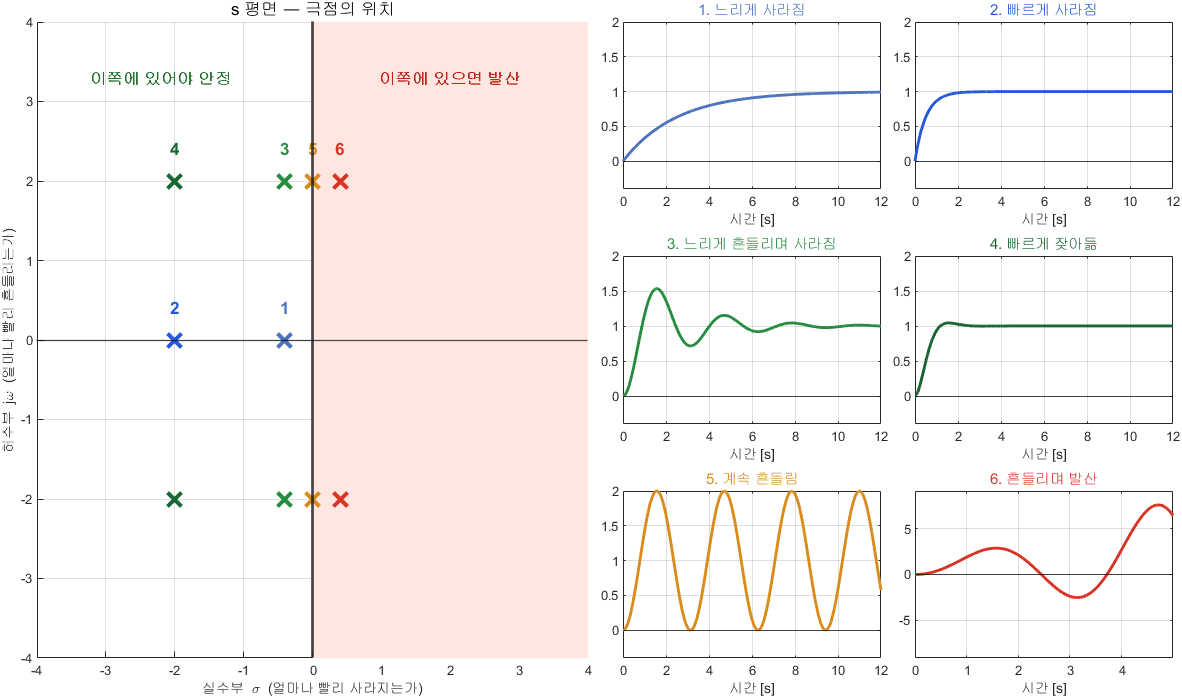

극점 위치와 응답 모양

fprintf('=== 안정도 판정 ===\n');
Gs = { '안정',     1/((s+1)*(s+3))
       '한계 안정', 1/(s^2+4)
       '불안정',   1/((s-1)*(s+3)) };
for i = 1:3
    p = pole(Gs{i,2});
    fprintf('  %-8s 극점 %-26s 최대 실수부 %+.2f\n', ...
            Gs{i,1}, mat2str(round(p.',3)), max(real(p)));
end
fprintf('\n');

## 6. 시스템의 차수

**차수**는 시스템을 기술하는 데 필요한 1계 미분방정식의 개수, 곧 **상태의 개수**이고 **극점의 개수**입니다.

물리적으로는 **에너지를 저장하는 곳의 개수**와 같습니다.

- RC 회로 — 커패시터 하나 $\rightarrow$ 1차

- 질량-스프링-댐퍼 — 스프링과 질량 $\rightarrow$ 2차

- DC 모터 — 인덕터와 관성 $\rightarrow$ 2차

차수가 높을수록 다룰 것이 많아지지만, 실제로는 **가장 느린 극점 몇 개**가 응답을 지배합니다. 그것을 **지배극점**이라고 합니다.

## 7. 1차 시스템


$$G(s) = \frac{K}{\tau s + 1}$$


숫자 두 개면 전부입니다.

- $K$ **직류이득** — 정상상태에서 몇 배로 나오는가

- $\tau$ **시정수** — 얼마나 빠른가

알아 둘 값들

- 극점은 $s = -1/\tau$

- $t = \tau$ 에서 최종값의 약 $63.2\%$ 에 도달

- 정착시간 $t_s \approx 4\tau$ ($2\%$ 기준)

- **오버슈트는 절대 없다** (극점이 실수 하나뿐이라 진동할 방법이 없다)

tau = 2;  Kdc = 1;
G1 = Kdc/(tau*s + 1);
t1 = (0:0.02:12)';
figure;
plot(t1, step(G1, t1), 'LineWidth', 2.5); hold on;
yline(Kdc, 'k--'); yline(0.632*Kdc, 'r:'); xline(tau, 'r:');
grid on; xlabel('시간 [s]'); ylabel('출력');
legend('응답', '최종값', 't = \tau 에서 63.2 %', 'Location','southeast');
title(sprintf('1차 시스템 (\\tau = %.1f s, 정착시간 약 %.1f s)', tau, 4*tau));

## 8. 2차 시스템


$$G(s) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$


숫자 두 개로 성격이 정해집니다.

- $\omega_n$ **고유진동수** — 빠르기

- $\zeta$ **감쇠비** — 얼마나 진동하는가

극점은 이렇습니다.


$$s = -\zeta\omega_n \pm j\,\omega_n\sqrt{1-\zeta^2}$$


이 식을 극좌표로 읽으면 의미가 그대로 보입니다.

- 원점까지의 **거리** $= \omega_n$ $\rightarrow$ 빠르기

- 실축에서 잰 **각도** $= \arccos\zeta$ $\rightarrow$ 진동 정도

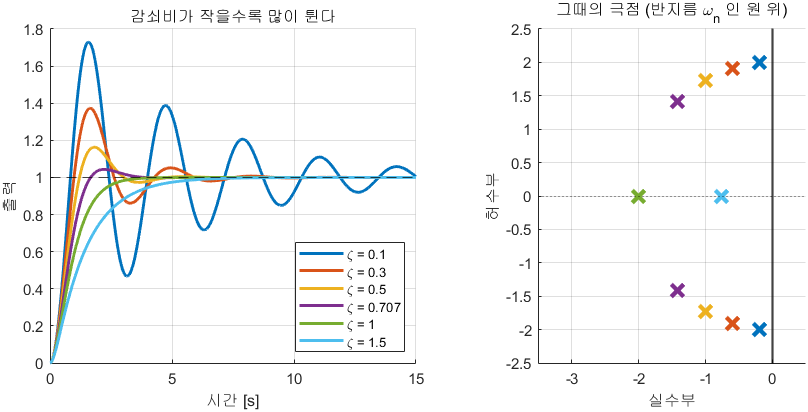

감쇠비와 극점 위치, 그리고 응답

## 8-1. 감쇠비에 따른 이름

| 감쇠비 | 극점 | 응답 | 이름 | |---|---|---|---| | $\zeta = 0$ | 순허수 | 계속 흔들림 | 무감쇠 | | $0 < \zeta < 1$ | 복소수 | 흔들리며 잦아듦 | 부족감쇠 | | $\zeta = 1$ | 실수 중근 | 진동 없이 가장 빠르게 | 임계감쇠 | | $\zeta > 1$ | 서로 다른 실수 | 진동 없이 느리게 | 과감쇠 |

성능과 이어지는 두 공식은 이것입니다.


$$\%OS = 100\,e^{-\zeta\pi/\sqrt{1-\zeta^2}}, \qquad t_s \approx \frac{4}{\zeta\omega_n}$$


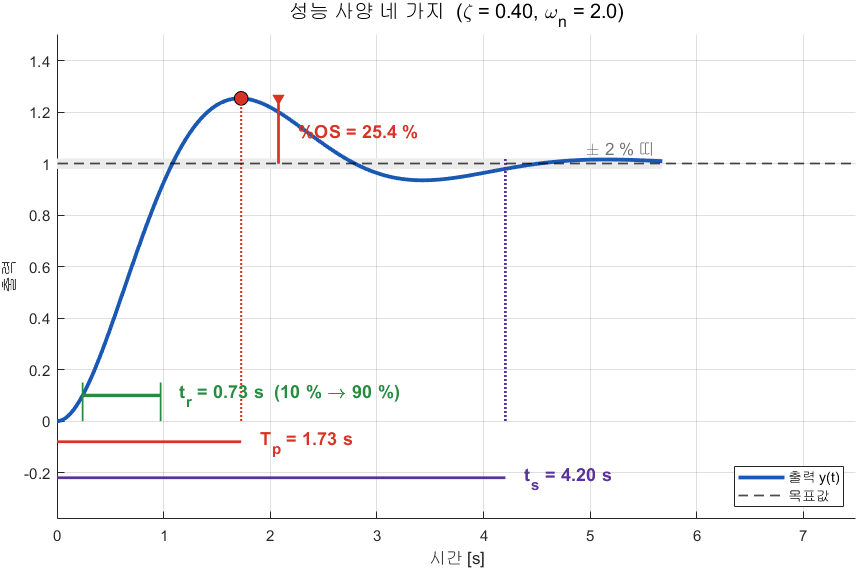

성능 사양 네 가지

fprintf('=== 감쇠비에 따른 성능 ===\n');
fprintf('  zeta    오버슈트[%%]  정착시간[s]   이름\n');
fprintf('  -----  -----------  -----------  ----------\n');
wn = 2;
for z = [0.1 0.3 0.5 0.707 1.0 1.5]
    G2 = wn^2/(s^2 + 2*z*wn*s + wn^2);
    ii = stepinfo(G2);
    if     z < 1,  nm2 = '부족감쇠';
    elseif z == 1, nm2 = '임계감쇠';
    else,          nm2 = '과감쇠';
    end
    fprintf('  %5.3f  %11.1f  %11.2f  %s\n', z, ii.Overshoot, ii.SettlingTime, nm2);
end
fprintf('\n  zeta = 0.707 을 좋아하는 이유 : 오버슈트가 5 %% 아래인데 정착이 빠릅니다.\n\n');

## 9. 정리

- 전체 응답 = **자유응답 + 강제응답**

- 안정도는 **극점의 실수부 부호**로 판정한다

- 차수 = 상태의 개수 = 극점의 개수 = **에너지를 저장하는 곳의 개수**

- 1차는 $\tau$ 하나, 2차는 $\zeta$ 와 $\omega_n$ 두 개로 성격이 정해진다

- 정현파를 넣고 재 본 결과를 모은 것이 **주파수응답**이다

이 과목의 4, 5 주차 내용과 그대로 이어집니다.